clear
clc
close all

%% Arena
arenaRadius = 38.5;          % cm (77 cm diameter)

%% Robot
robotWidth  = 10;
robotLength = 10;

robotX = 0;
robotY = -25;

%% -----------------------------
% Sensor Locations
%% -----------------------------

sensorPos = [
     0   robotY+robotLength/2;     % Front centre
    -5   robotY;                   % Left side
     5   robotY                    % Right side
];

%% Sensor Headings

heading = [
    90     % Front
   135     % Left side
    45      % Right side
];

%% -----------------------------
% Measured Detection Envelope
%% -----------------------------

%% Effective envelope from measurements
angle = [0 5 10 15 20];

range = [80 80 78 72 55];

% Mirror it
theta = [-fliplr(angle) angle];
radius = [fliplr(range) range];


%% -----------------------------
% Plot
%% -----------------------------

figure
hold on
axis equal
grid on

%% Dohyo

t = linspace(0,2*pi,400);

plot(arenaRadius*cos(t),...
     arenaRadius*sin(t),...
     'k','LineWidth',2)

%% Robot

rectangle('Position',...
[-robotWidth/2 robotY-robotLength/2 robotWidth robotLength],...
'FaceColor',[0.5 0.5 0.5],...
'EdgeColor','k',...
'LineWidth',2)

%% Sensors

plot(sensorPos(:,1),sensorPos(:,2),...
    'ro',...
    'MarkerFaceColor','r',...
    'MarkerSize',8)

%% Coverage

for i=1:3

    th = deg2rad(theta + heading(i));

    x = sensorPos(i,1) + radius.*cos(th);
    y = sensorPos(i,2) + radius.*sin(th);

    %% Clip to arena

    d = hypot(x,y);

    idx = d>arenaRadius;

    x(idx)=x(idx).*arenaRadius./d(idx);
    y(idx)=y(idx).*arenaRadius./d(idx);

    fill([sensorPos(i,1) x sensorPos(i,1)],...
         [sensorPos(i,2) y sensorPos(i,2)],...
         [0.25 0.65 1],...
         'FaceAlpha',0.35,...
         'EdgeColor','b',...
         'LineWidth',1.5)

    %% Centre line

    plot([sensorPos(i,1) sensorPos(i,1)+arenaRadius*cosd(heading(i))],...
         [sensorPos(i,2) sensorPos(i,2)+arenaRadius*sind(heading(i))],...
         '--b',...
         'LineWidth',1)

end

%% Labels

text(0,robotY,'Robot',...
    'HorizontalAlignment','center',...
    'Color','w',...
    'FontWeight','bold')

title('Coverage of Three VL53L0X Sensors')
xlabel('X Position (cm)')
ylabel('Y Position (cm)')

xlim([-42 42])
ylim([-40 42])

%% ==========================================================
% Layouts
%% ==========================================================

layouts(1).name = '3 Front';
layouts(1).sensorPos = [
    -3.5 robotY+robotLength/2;
     0   robotY+robotLength/2;
     3.5 robotY+robotLength/2];
layouts(1).heading = [110 90 70];

layouts(2).name = 'Front + Side';
layouts(2).sensorPos = [
     0  robotY+robotLength/2;
    -5  robotY;
     5  robotY];
layouts(2).heading = [90 135 45];

layouts(3).name = 'Front corners';
layouts(3).sensorPos = [
    -4.5 robotY+4.5;
     0   robotY+robotLength/2;
     4.5 robotY+4.5];
layouts(3).heading = [120 90 60];

layouts(4).name = 'Front + Side + Rear';
layouts(4).sensorPos = [
     0   robotY+robotLength/2;
    -4.5 robotY+4.5;
     4.5 robotY+4.5;
     0   robotY-robotLength/2];
layouts(4).heading = [90 135 45 270];

layouts(5).name = 'Four Corners';
layouts(5).sensorPos = [
    -4.5 robotY+4.5;
     4.5 robotY+4.5;
    -4.5 robotY-4.5;
     4.5 robotY-4.5];
layouts(5).heading = [135 45 225 315];

layouts(6).name = 'Four front';
layouts(6).sensorPos = [
    -4.5 robotY+robotLength/2;
    -1.5 robotY+robotLength/2;
     1.5 robotY+robotLength/2;
     4.5 robotY+robotLength/2];
layouts(6).heading = [120 100 80 60];

%% ==========================================================
% Option 7 - Front + Mid-Side + Rear
%% ==========================================================

layouts(7).name = 'Front + mid-side + rear';

layouts(7).sensorPos = [

     0    robotY + robotLength/2;      % Front centre

    -5    robotY;                      % Mid left side

     5    robotY;                      % Mid right side

     0    robotY - robotLength/2;      % Rear

];

layouts(7).heading = [

     90;      % Front

    150;      % Left sensor

     30;      % Right sensor

    270;      % Rear

];
%% ==========================================================
% Option 8 - Two Front + Two Angled Side
%% ==========================================================

layouts(8).name = 'Two Front + Two Angled Side';

layouts(8).sensorPos = [

    -4.0   robotY + robotLength/2;      % Front left
     4.0   robotY + robotLength/2;      % Front right

    -5.0   robotY;                      % Left side
     5.0   robotY;                      % Right side

];

layouts(8).heading = [

   100;     % Front left
     80;     % Front right

    140;     % Left side, 30° forward
     40;     % Right side, 30° forward

];

figure('Position',[100 100 1400 800])

nLayouts = length(layouts);

nCols = 4;
nRows = 2;

for L = 1:nLayouts

    subplot(nRows,nCols,L)
    hold on
    axis equal
    box on
    grid on

    % Arena
    t = linspace(0,2*pi,500);
    plot(arenaRadius*cos(t),arenaRadius*sin(t),'k','LineWidth',1.5)

    % Robot
    rectangle('Position',...
        [-robotWidth/2,...
         robotY-robotLength/2,...
         robotWidth,...
         robotLength],...
        'FaceColor',[0.6 0.6 0.6],...
        'EdgeColor','k');

    sensorPos = layouts(L).sensorPos;
    heading = layouts(L).heading;

    % Sensors
    plot(sensorPos(:,1),sensorPos(:,2),...
        'ro','MarkerFaceColor','r','MarkerSize',6)

    % Coverage
    for n = 1:size(sensorPos,1)

        th = deg2rad(theta + heading(n));

        x = sensorPos(n,1) + radius.*cos(th);
        y = sensorPos(n,2) + radius.*sin(th);

        d = hypot(x,y);
        idx = d > arenaRadius;

        x(idx) = x(idx).*arenaRadius./d(idx);
        y(idx) = y(idx).*arenaRadius./d(idx);

        fill([sensorPos(n,1) x sensorPos(n,1)],...
             [sensorPos(n,2) y sensorPos(n,2)],...
             [0.3 0.7 1],...
             'FaceAlpha',0.35,...
             'EdgeColor','b');

    end

    title(layouts(L).name)

    xlim([-40 40])
    ylim([-38 40])

end

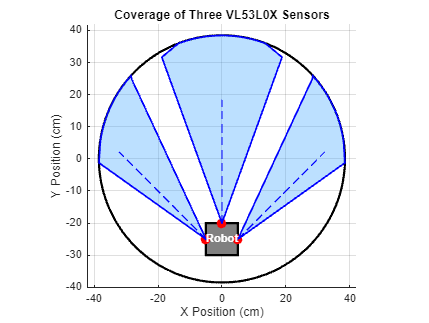

clear
clc
close all

%% Actual distances (cm)
actual = [2 3 4 5 10 15 20 25 50 60 70 80];

%% Measured values (NaN = no detection)

Z = [
2.1 3.1 4.2 5.1 10.2 15.1 20.3 25.2 50.6 60.5 70.7 80.4;
2.2 3.0 4.1 5.2 10.3 15.3 20.5 25.4 50.8 60.7 71.0 80.8;
2.3 3.2 4.2 5.3 10.5 15.6 20.8 25.8 51.5 61.8 72.0 81.6;
2.4 3.3 4.5 5.7 11.2 16.8 18.4 27.6 43.8 56.5 NaN NaN;
2.7 3.8 5.2 6.5 12.8 18.9 29.4 21.7 NaN NaN NaN NaN;
10.1 88.5 77.3 60.5 NaN NaN 88.3 NaN NaN NaN NaN NaN;
77.5 30.5 NaN 74.3 75.1 NaN NaN NaN NaN NaN NaN NaN;
];

angles = [0 5 10 20 30 45 60];

%% Plot

figure
hold on
grid on
box on

colors = lines(length(angles));

for i = 1:length(angles)

    valid = ~isnan(Z(i,:));

    plot(actual(valid),...
         Z(i,valid),...
         'o',...
         'MarkerFaceColor',colors(i,:),...
         'MarkerEdgeColor','k',...
         'MarkerSize',7)

end

%% Perfect measurement line

plot([0 85],[0 85],...
    'k--',...
    'LineWidth',2)

xlabel('Actual (cm)')
ylabel('Measured (cm)')

title('VL53L0X Measured vs Actual Distance')

legend(...
'0°','5°','10°','20°','30°','45°','60°',...
'Exact match',...
'Location','eastoutside')

xlim([0 85])
ylim([0 95])